clear;

# BHZ 3D tetra

## useful tool

s_0   = pauli_matric(0)  ;  s_x = pauli_matric(1);  s_y =  pauli_matric(2) ;  s_z = pauli_matric(3);
sigma_0 = pauli_matric(0);sigma_x =  pauli_matric(1);sigma_y =  pauli_matric(2);sigma_z = pauli_matric(3);
tau_0   = pauli_matric(0);  tau_x =  pauli_matric(1);  tau_y =  pauli_matric(2);  tau_z = pauli_matric(3);

syms C0 C1 C2 real;
syms M0 M1 M2 real;
syms A0 A1 A2 B real;
syms k_x k_y k_z real;
%
M       = -M0+M2*(k_x^2+k_y^2)+M1*(k_z^2);
E0k     = C0+C2*(k_x^2+k_y^2)+C1*(k_z^2);
A       = A0+A2*(k_x^2+k_y^2)+A1*(k_z^2);
k_plus  = k_x + 1i* k_y;
k_minus = k_x - 1i* k_y;
%
BHZ = HK(4,3);
%
BHZ = BHZ ...
    +Term(A*k_x ,sigma_z*tau_x )...
    +Term(A*k_y ,sigma_0*tau_y )...
    +Term(E0k   ,sigma_0*tau_0 )...
    +Term(M     ,sigma_0*tau_z )...
    +Term(B*k_z*(k_x^2-k_y^2),sigma_x*tau_x )...
    +Term(2*B*k_z*(k_x*k_y),sigma_y*tau_x )...
    ;

Setting 4/4 term into HK ...


Setting 4/4 term into HK ...


Setting 4/4 term into HK ...


Setting 4/4 term into HK ...


Setting 2/2 term into HK ...


Setting 1/1 term into HK ...


C0     = 0;
A1     =  0    ;
A2     =  0    ;
BHZ = BHZ.Subsall('sym');

% unit eV 
C0     = -0.0   ;
M0     = -1   ;
%M0     = -0.25   ;
% unit eV Ang
A0      =  1      ;
%B      =  4.1      ;
% unit eV Ang^2
C1     =  0     ;
C2     =  0     ;
M1     =  -0.5      ;
M2     =  -0.5  ;
B     =  0.5    ;
% unit    Ang
a      =  1        ;
b      =  1       ;
c      =  1        ;
BHZ = BHZ <'POSCAR';

BHZ_TB= BHZ.kp2TB();

% bandplot
BHZ_TB_n = BHZ_TB.Subsall();
BHZ_TB_n = BHZ_TB_n <'KPOINTS';
BHZ_TB_super_n = BHZ_TB_n.supercell_hr([1,1,0;-1,1,0;0,0,1]);

Search done; begin set hoppings
We can improve the perfomance later
Generate process: SUPERCELL(1,2) NRPT(1,23) RUNINGTIME: 0.067473 s.
Generate process: SUPERCELL(1,2) NRPT(2,23) RUNINGTIME: 0.162051 s.
Generate process: SUPERCELL(1,2) NRPT(3,23) RUNINGTIME: 0.271146 s.
Generate process: SUPERCELL(1,2) NRPT(4,23) RUNINGTIME: 0.359086 s.
Generate process: SUPERCELL(1,2) NRPT(5,23) RUNINGTIME: 0.422344 s.
Generate process: SUPERCELL(1,2) NRPT(6,23) RUNINGTIME: 0.520938 s.
Generate process: SUPERCELL(1,2) NRPT(7,23) RUNINGTIME: 0.600753 s.
Generate process: SUPERCELL(1,2) NRPT(8,23) RUNINGTIME: 0.698791 s.
Generate process: SUPERCELL(1,2) NRPT(9,23) RUNINGTIME: 0.811236 s.
Generate process: SUPERCELL(1,2) NRPT(10,23) RUNINGTIME: 0.912739 s.
Generate process: SUPERCELL(1,2) NRPT(11,23) RUNINGTIME: 0.997956 s.
Generate process: SUPERCELL(1,2) NRPT(12,23) RUNINGTIME: 1.125228 s.
Generate process: SUPERCELL(1,2) NRPT(13,23) RUNINGTIME: 1.289533 s.
Generate process: SUPERCELL(1,2) NRPT(14,23)

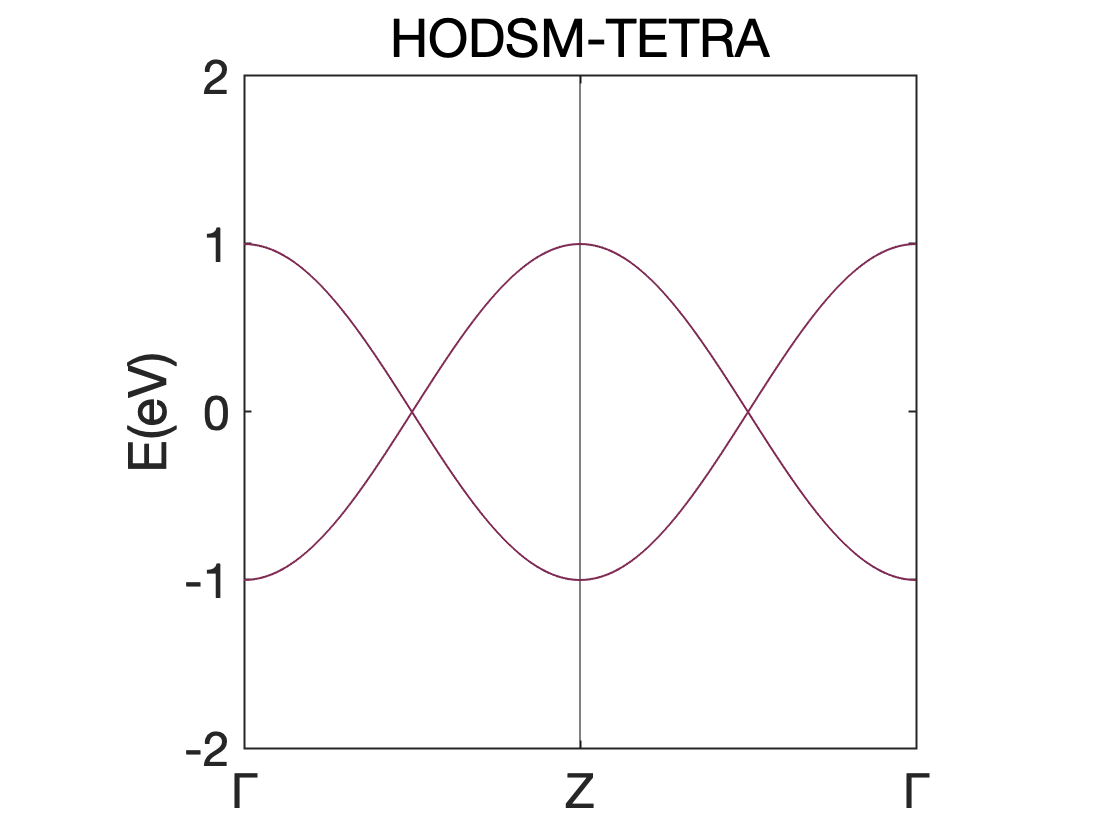

EIGENCAR = BHZ_TB_super_n.EIGENCAR_gen();
bandplot(EIGENCAR,[-2,2],'title',"HODSM-TETRA");

% BHZ_TB_super_n.orbL = zeros(8,3);

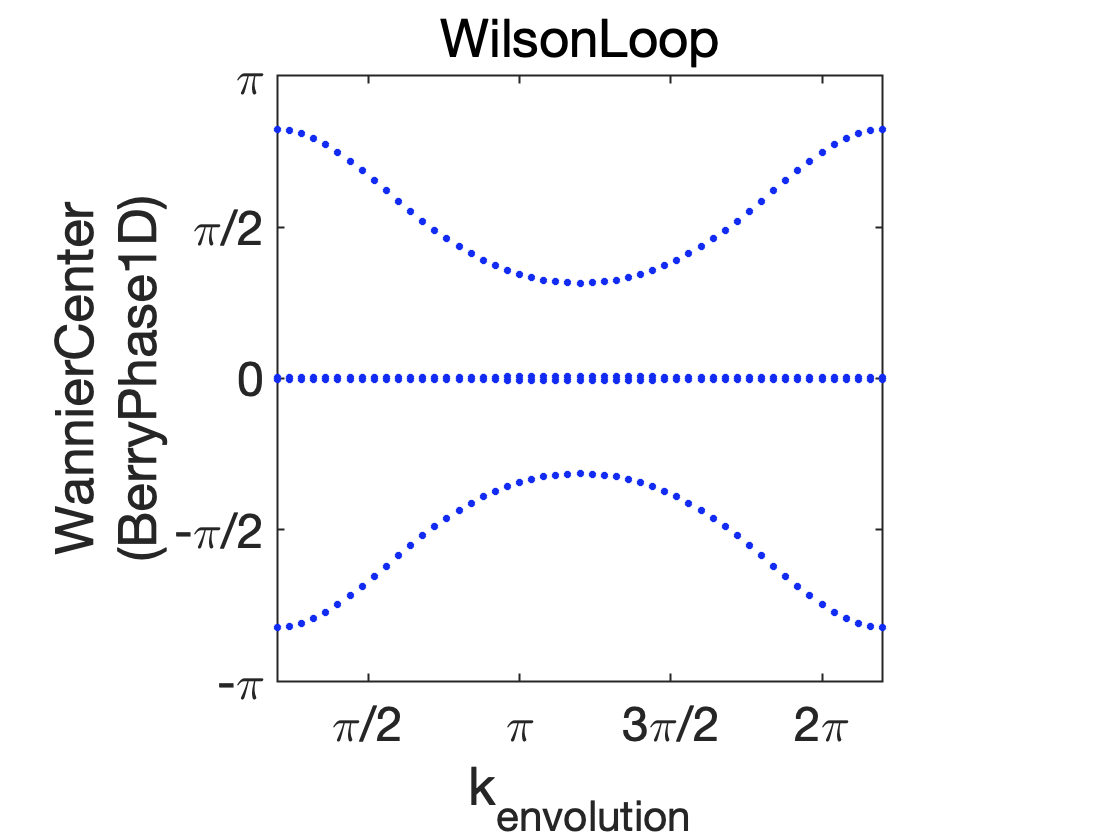

[BFCAR,~,klist_l] = BHZ_TB_super_n.WilsonLoop('knum_int',31,'kstart',[0,0,0.1],'kevolution',[1,0,0],'kintegral',[0,1,0]);
[fig,ax] = vasplib.WilsonLoopPlot(BFCAR,klist_l);

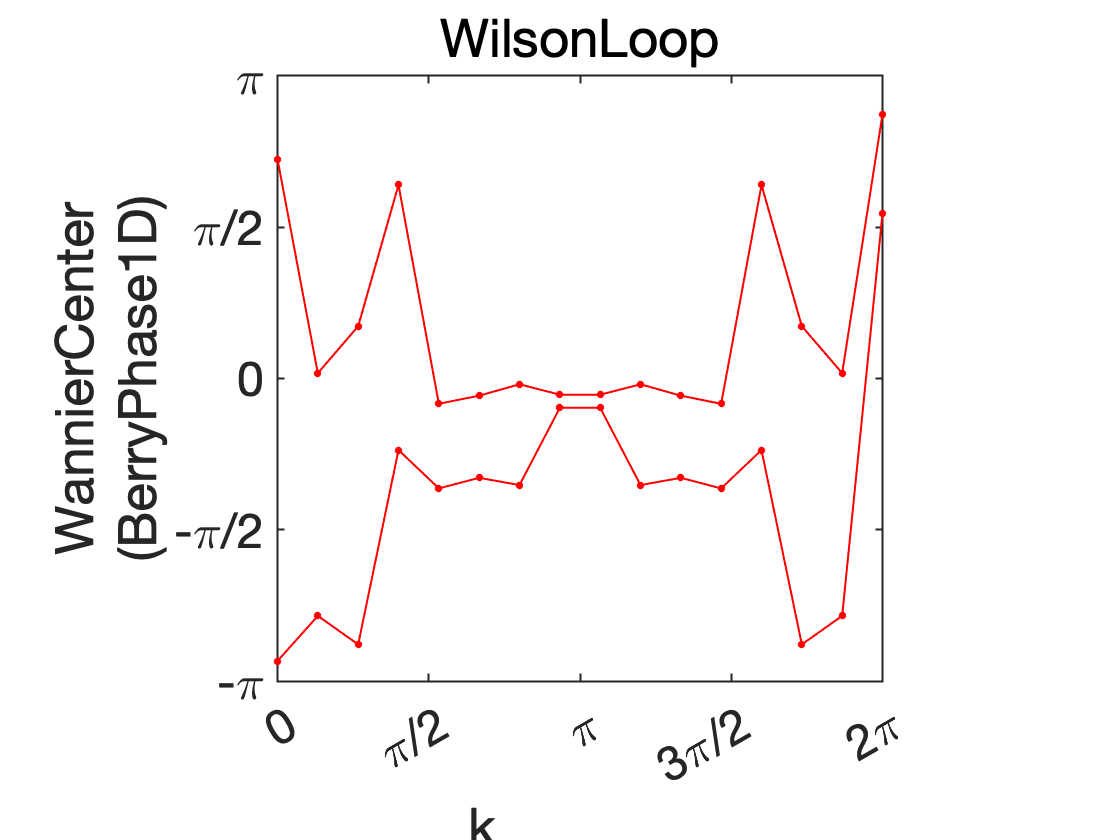

[nested_BFCAR,~,nested_klist_l] = BHZ_TB_super_n.nested_WilsonLoop('knum_evol',16);
[fig2,ax2] = vasplib.WilsonLoopPlot((nested_BFCAR),nested_klist_l,'LineSpec','-o','Color','r');

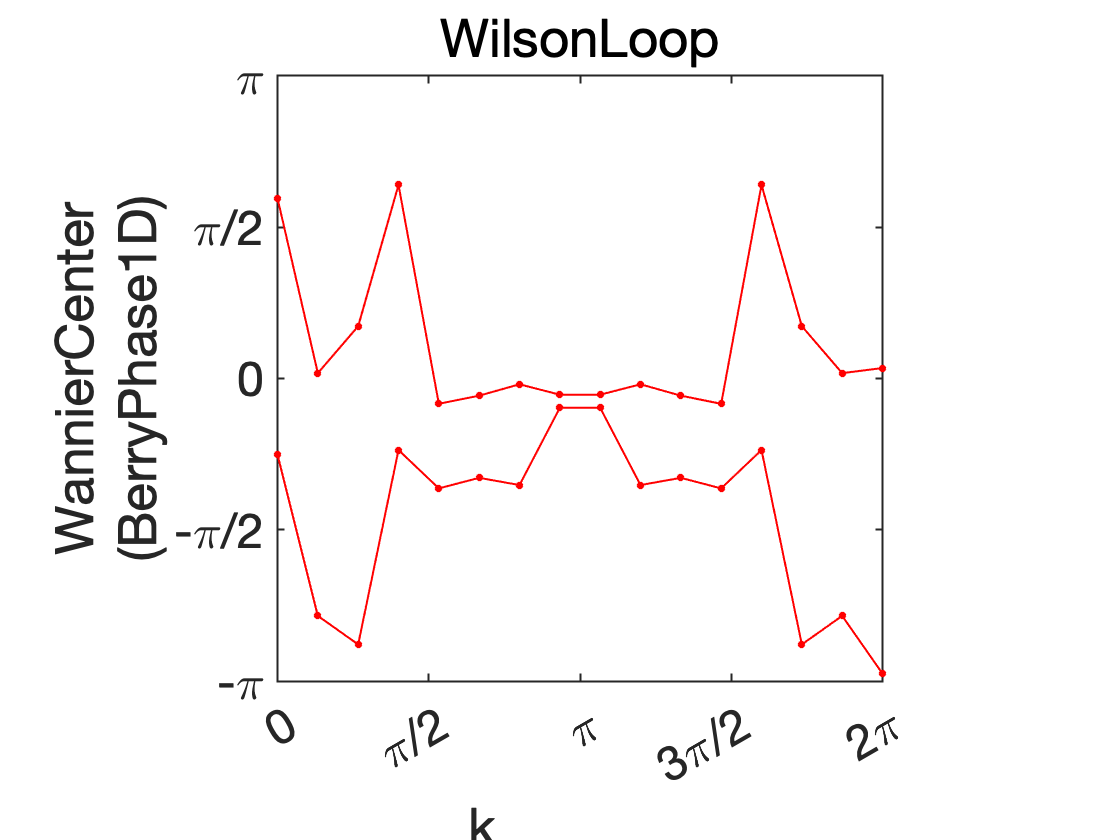

[nested_BFCAR,~,nested_klist_l] = BHZ_TB_super_n.nested_WilsonLoop('knum_evol',16,'kevolution',[0,1,0],'kintegral',[1,0,0]);
[fig2,ax2] = vasplib.WilsonLoopPlot((nested_BFCAR),nested_klist_l,'LineSpec','-o','Color','r');